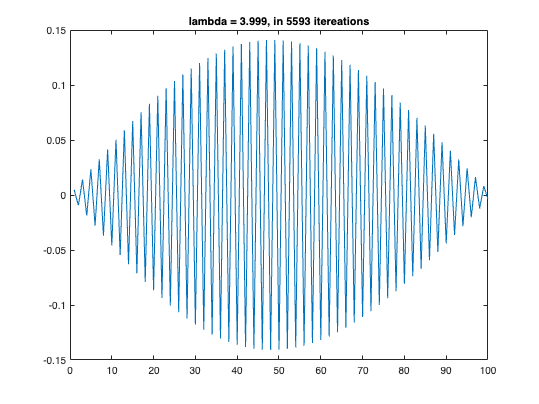

N = 100;
A = diag(2*ones(1,N)) + diag(-1*ones(1,N-1),1) + diag(-1*ones(1,N-1),-1);
v0 = zeros(N-1,1);
v0 = [1; v0];
[v, lambda,iter] = PowerIteration(A,v0,10000, 0.0001);

plot(v)
title(append( 'lambda = ', string(lambda),', in ', string(iter), ' itereations' )   );  

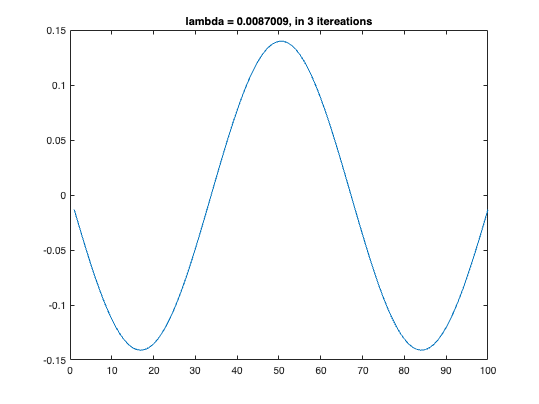

v0 = ones(N,1)/sqrt(N);
[v, lambda,iter] = RayleighQuotient(A,v0,10000, 0.0001);

plot(v)
title(append( 'lambda = ', string(lambda),', in ', string(iter), ' itereations' )   );   

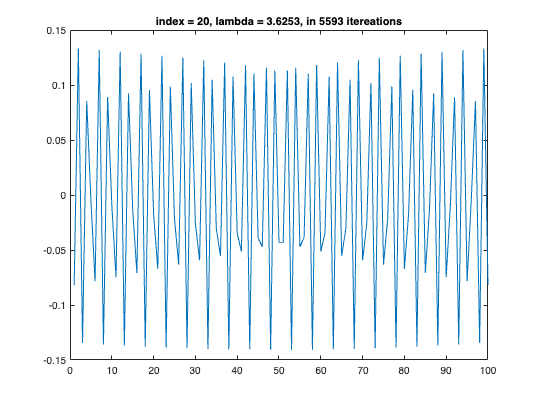


[V,Lambda,iter] = QRIteration(A,10000,0.0001);

i=20;
plot(V(1:N, i));
title(append('index = ', string(i) , ', lambda = ', string(Lambda(i,1)),', in ', string(iter), ' itereations' )   );   

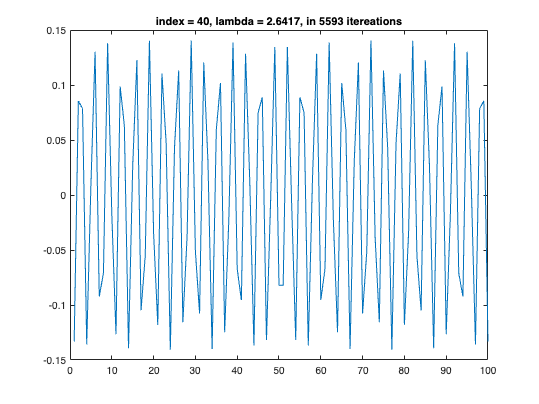


i=40;
plot(V(1:N, i));
title(append( 'index = ', string(i) , ', lambda = ', string(Lambda(i,1)),', in ', string(iter), ' itereations' )   );   

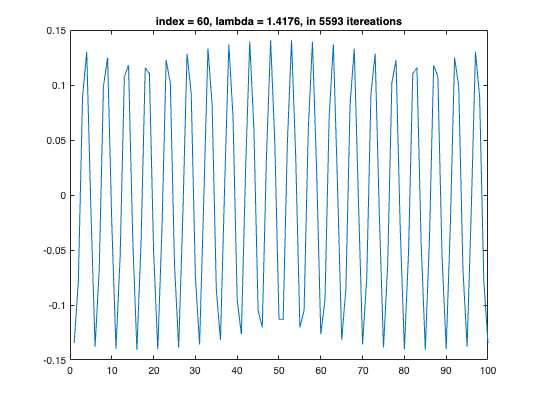


i=60;
plot(V(1:N, i));
title(append('index = ', string(i) , ', lambda = ', string(Lambda(i,1)),', in ', string(iter), ' itereations' )   );   

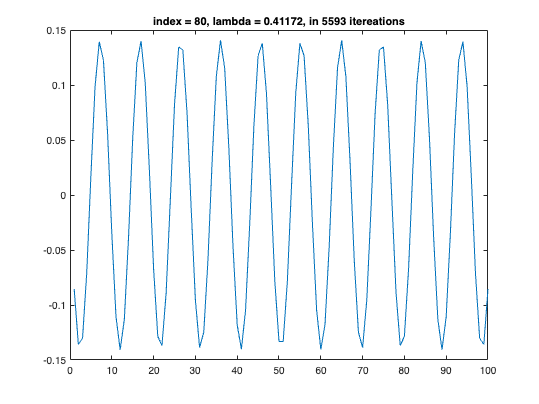


i=80;
plot(V(1:N, i));
title(append( 'index = ', string(i) , ', lambda = ', string(Lambda(i,1)),', in ', string(iter), ' itereations' )   );   

function [v,lambda,iter] = PowerIteration(A,v0,maxiter,tol)
    v = v0;
    for iter = 1:maxiter
        w = A * v;
        v = w / norm(w); 
        lambda = transpose(v) * A * v;
        err = norm(A*v - lambda * v);
        if (err < tol)
            return
        end
    end

end 


function [v,lambda,iter] = RayleighQuotient(A,v0,maxiter,tol)
    v = v0;
    lambda = transpose(v0) * A * v0;
    N = size(A,1);
    for iter = 1:maxiter
        M = A - lambda * eye(N);
        w = M \ v;
        v = w / norm(w);
        lambda = transpose(v) * A * v;
        err = norm(A*v - lambda * v);
        if (err < tol)
            return
        end

    end
end

function [V,Lambda,iter] = QRIteration(A,maxiter,tol)
    originalA = A;
    N = size(A,1);
    V = eye(N);
    for iter = 1:maxiter
        [q,r] = qr(A);
        A = r*q;
        V = V*q;
        Lambda = diag(A);

        for c = 1:N

            err = norm(V(1:N, c) * A(c,c)- originalA * V(1:N, c));
            if err>tol  
                break
            end
            return
        end
        
    end
    
end

